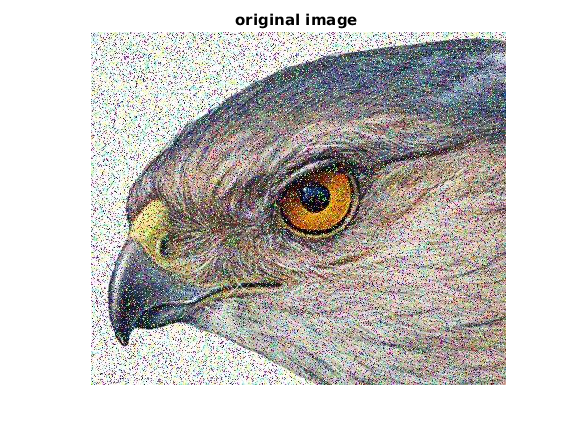

clc;
clear all;
close all;

I = imread('IMG_EF9C94268C2B-1.png');
Im=im2gray(I);
figure, imshow(I) ,title('original image ');

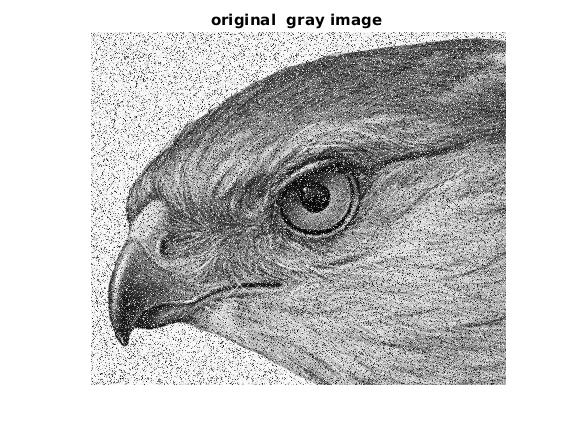

figure, imshow(Im),title('original  gray image ');

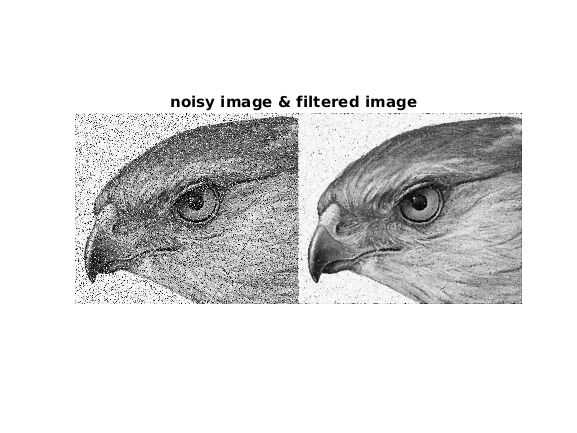


%% this is a salt pepper noise 


J = imnoise(Im,'salt & pepper',0.02);

%%for  salt and pepper noise median is the best filter 
K = medfilt2(J);
imshowpair(J,K,'montage'),title('noisy image & filtered image  ');